NumBits = 100;
msgBits = randi(2, [NumBits,1]) - 1;
% constellation = 1/sqrt(2)*[1+1j; -1+1j; -1-1j; 1-1j];
constellation = [-1 ; 1];
R = log2(length(constellation));

%Encoder
numReps = 5;
encodedBits = myEncoder(msgBits, numReps);

%Interleaver
rowKey = 100;
interleavedBits = myInterleaver(encodedBits, rowKey);

bitsTransmitted = interleavedBits;

% modulation
modSymbols = myModulator(bitsTransmitted, constellation);
len = length(modSymbols);

% channel
unitNoise = (randn(len, 1)) + 1j*(randn(len, 1));
Noise = unitNoise;
Noisy_modSymbols = modSymbols + Noise;

% de modulation
[decModSymbols, bitsReceived] = myDemodulator(Noisy_modSymbols, constellation);
[bitsReceived, bitsTransmitted];

%De-Interleaver
deinterleavedBits = myDeinterleaver(bitsReceived, rowKey);

%Decoder
decodedBits = myDecoder(deinterleavedBits, numReps);
rxmsgBits = decodedBits;

sum(msgBits ~= rxmsgBits)

ans = 7

numReps = 3;
NumBits = 10000;
msgBits = randi(2, [NumBits,1]) - 1;
rowKey = 100;

R = 1/numReps;
EbNodb = -1:1:15;
BER_CC = zeros(1, length(EbNodb));

for ii = 1:length(EbNodb)
    
    EbNo = 10^(EbNodb(ii)/10);   
    sigma = sqrt(1/(2*R*EbNo));
    

%        Encoding
    encodedBits = myEncoder(msgBits, numReps);

%     Interleaving
    interleavedBits = myInterleaver(encodedBits, rowKey);

    bitsTransmitted = interleavedBits;

% bit to symbol mapping and modulation
    modSymbols = myModulator(bitsTransmitted, constellation);
    len = length(modSymbols);
    unitNoise = (randn(len, 1)) + 1j*(randn(len, 1));
    Noise = sigma.*unitNoise;

%     Channel
    Noisy_modSymbols = modSymbols + Noise ;

% demodulation and symbol to bit de-mapper
    [decModSymbols, bitsReceived] = myDemodulator(Noisy_modSymbols, constellation);

%     De-Interleaver
    deinterleavedBits = myDeinterleaver(bitsReceived, rowKey);

%     Decoder
    decodedBits = myDecoder(deinterleavedBits, numReps);

    rxmsgBits = decodedBits;

    BER_CC(1,ii) = sum(msgBits ~= rxmsgBits)/NumBits;

end

numReps = 1;
NumBits = 100000;
msgBits = randi(2, [NumBits,1]) - 1;
rowKey = 100;

R = 1/numReps;
EbNodb = -1:1:15;
BER_UC = zeros(1, length(EbNodb));
BER_th = zeros(1, length(EbNodb));

for ii = 1:length(EbNodb)
    
    EbNo = 10^(EbNodb(ii)/10);   
    sigma = sqrt(1/(2*R*EbNo));
    

%        Encoding
    encodedBits = myEncoder(msgBits, numReps);

%     Interleaving
    interleavedBits = myInterleaver(encodedBits, rowKey);

    bitsTransmitted = interleavedBits;

% bit to symbol mapping and modulation
    modSymbols = myModulator(bitsTransmitted, constellation);
    len = length(modSymbols);
    unitNoise = ((randn(len, 1)) + 1j*(randn(len, 1)));
    Noise = sigma.*unitNoise;

%     Channel
    Noisy_modSymbols = modSymbols + Noise ;

% demodulation and symbol to bit de-mapper
    [decModSymbols, bitsReceived] = myDemodulator(Noisy_modSymbols, constellation);

%     De-Interleaver
    deinterleavedBits = myDeinterleaver(bitsReceived, rowKey);

%     Decoder
    decodedBits = myDecoder(deinterleavedBits, numReps);

    rxmsgBits = decodedBits;

    BER_UC(1,ii) = sum(msgBits ~= rxmsgBits)/NumBits;
    BER_th(1,ii) = 0.5*erfc(sqrt(EbNo));
end

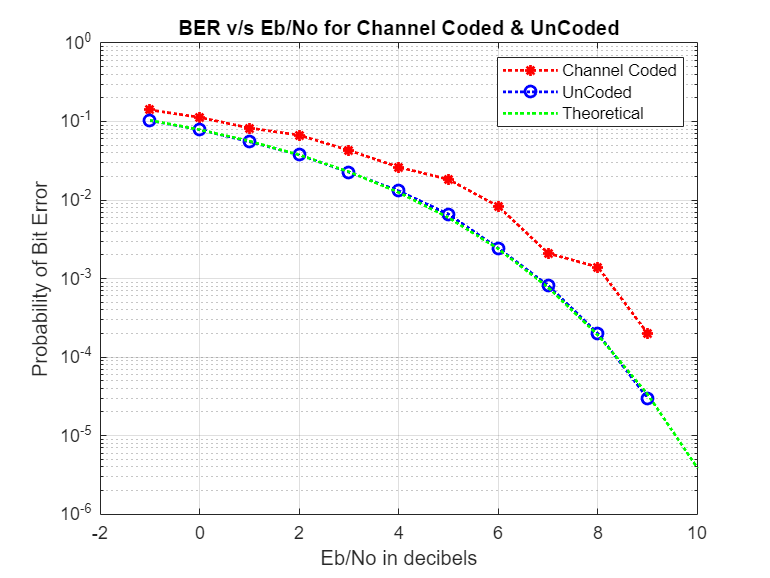

figure();
p = semilogy(EbNodb, BER_CC);
p.LineStyle = ":";
p.Color = "red";
p.Marker = "*";
set(p, 'LineWidth',1.5);
hold on;

p = semilogy(EbNodb, BER_UC);
p.LineStyle = ":";
p.Color = "blue";
p.Marker = "o";
set(p, 'LineWidth',1.5);

p = semilogy(EbNodb, BER_th);
p.LineStyle = ":";
p.Color = "green";
set(p, 'LineWidth',1.5);

legend('Channel Coded','UnCoded', 'Theoretical')
grid();
title('BER v/s Eb/No for Channel Coded & UnCoded');
xlabel('Eb/No in decibels') ;
ylabel('Probability of Bit Error');
xlim([-2 10]);

% SNR_DB = -1:.2:15;
% BER = zeros(1,length(SNR_DB));
% for ii = 1:length(SNR_DB)
%         
%      SNR = 10^SNR_DB(ii)/10;
%      Noise = unitNoise/SNR;
%      Noisy_modSymbols = modSymbols + Noise;
% 
%      [decModSymbols, bitsReceived] = myDemodulator(Noisy_modSymbols, constellation);
%      BER(1,ii) = sum(bitsReceived ~= bitsToSend)/NumBits;
% 
% end
% 
% p = semilogy(SNR_DB, BER);
% p.LineStyle = ":";
% p.Color = "red";
% p.Marker = "*";
% grid()